# **Derive dynamic equations for quadrupedal robot**

**By. Jungill Kang**

Start by writing "derive_impedance_control" on the command window.

Derive impedance controller for simple 2 dof actuator.

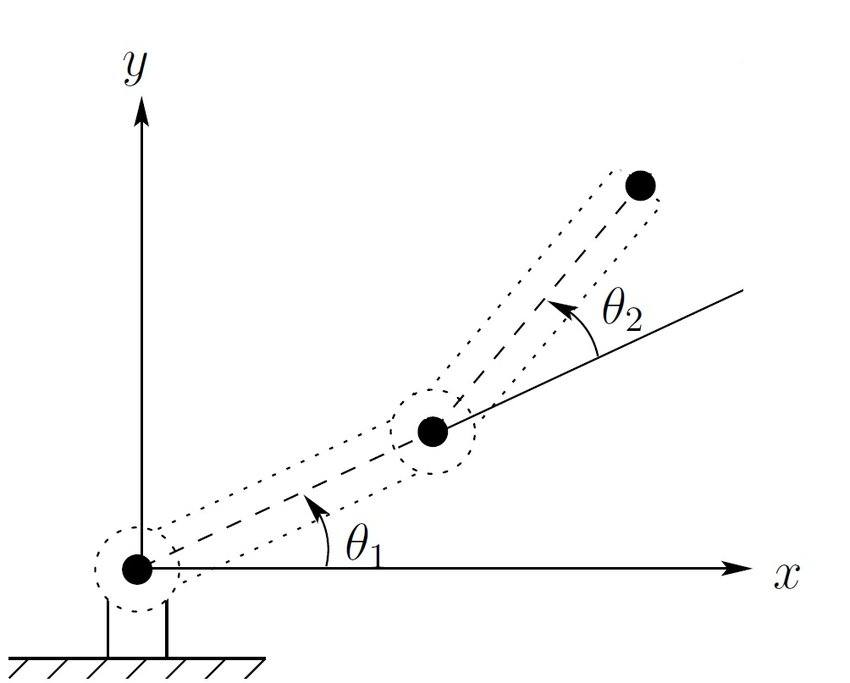

function derive_impedance_control

syms l1 l2 theta1 theta2 theta1d theta2d real

q = [theta1 theta2];

x = l1*cos(theta1+3*pi/2) + l2*cos(theta1+theta2+3*pi/2);
y = l1*sin(theta1+3*pi/2) + l2*sin(theta1+theta2+3*pi/2);

r = simplify(sqrt(x^2+y^2));
theta = atan2(x,y);

J_r = jacobian(r,q); % jacobian in r direction
J_t = jacobian(theta,q); % jacobian in theta direction

Now for the system derive the equation of the motion.

m1 = 1; I1 = 0.1; m2 = 1; I2 = 0.1;
c1 = 0.5; c2 = 0.5;
l = 1; g = 9.81;
fps = 30;

parms.m1 = m1; parms.m2 = m2; 
parms.I1 = I1; parms.I2 = I2;
parms.c1 = c1; parms.c2 = c2;
parms.l = l; parms.g = g;
parms.control.dr = 1.5; parms.control.dt = 0; % desired r and theta
parms.control.drd = 0; parms.control.dtd = 0; % desired r dot and theta dot
parms.control.kr = 500; parms.control.kt = 10;
parms.control = 0; % 0 for off, 1 for on

t = linspace(0,10); %time values
z0 = [pi/2 0 0 0];
options = odeset('Abstol',1e-10,'Reltol',1e-10);
[t, z] = ode45(@rhs,t,z0,options,parms); %integrate using ode45

Some plots

figure(1)
subplot(2,1,1)
plot(t,z(:,1),'r--','Linewidth',3); hold on
plot(t,z(:,3),'b','Linewidth',2);
ylabel('position','Fontsize',12);
title('Pendulum position and velocity as a function of time','Fontsize',12);
legend('\theta_1','\theta_2','Location','best','Fontsize',12);
subplot(2,1,2)
plot(t,z(:,2),'r--','Linewidth',3); hold on
plot(t,z(:,4),'b','Linewidth',2);
ylabel('velocity','Fontsize',12);
xlabel('time','Fontsize',12);
legend('\theta_1','\theta_2','Location','best','Fontsize',12);

%check energy
% for i=1:length(t)
%     theta1 = z(i,1); omega1 = z(i,2);
%     theta2 = z(i,3); omega2 = z(i,4);
%     KE(i) = (m2*((omega1*(c2*sin(theta1 + theta2) + l*sin(theta1)) + c2*omega2*sin(theta1 + theta2))^2 + (omega1*(c2*cos(theta1 + theta2) + l*cos(theta1)) + c2*omega2*cos(theta1 + theta2))^2))/2 + (I2*(omega1 + omega2)^2)/2 + (I1*omega1^2)/2 + (m1*(c1^2*omega1^2*cos(theta1)^2 + c1^2*omega1^2*sin(theta1)^2))/2;
%     PE(i) = - g*m2*(c2*cos(theta1 + theta2) + l*cos(theta1)) - c1*g*m1*cos(theta1);
%     TE(i) = KE(i)+PE(i);
% end
% 
% figure(2)
% plot(t,TE,'r');
% title('Pendulum total energy as a function of time','Fontsize',12);
% ylabel('Energy','Fontsize',12);
% xlabel('time','Fontsize',12);

figure(3)
animate(t,z,parms,fps);

end

### Function for the simulation

function zdot = rhs(t,z,parms)

m1 = parms.m1; m2 = parms.m2;
I1 = parms.I1; I2 = parms.I2;
c1 = parms.c1; c2 = parms.c2;
l = parms.l; g = parms.g;
dr = parms.control.dr; dt = parms.control.dt; % desired r and theta
drd = parms.control.drd; dtd = parms.control.dtd; % desired r dot and theta dot
kr = parms.control.kr; kt = parms.control.kt;
control = parms.control; % 0 for off, 1 for on

theta1 = z(1);
omega1 = z(2);
theta2 = z(3);
omega2 = z(4);

% turn on the controller
if control == 1
    tau_1, tau_2 = controller(theta1,theta2,dr,dt,drd,dtd,kr,kt);
else
    tau_1 = 0; %shoulder torque
    tau_2 = 0; %-0.5*omega2; %-100*(theta2-pi/2); % 1, 10, 100 %elbow torque
end

tau = [tau_1; tau_2];

M11 = I1 + I2 + (m2*(2*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1))^2 + 2*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1))^2))/2 + (m1*(2*c1^2*cos(theta1)^2 + 2*c1^2*sin(theta1)^2))/2;
M12 = I2 + (m2*(2*c2*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1))*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + 2*c2*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1))*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))))/2;
M21 = I2 + (m2*(2*c2*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1))*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + 2*c2*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1))*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))))/2;
M22 = I2 + (m2*(2*c2^2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))^2 + 2*c2^2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))^2))/2;
C1 = -(m2*omega2*(2*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1))*(c2*omega1*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - 2*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1))*(c2*omega1*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + 2*c2*(omega1*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - 2*c2*(omega1*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))))/2;
C2 = (m2*(2*(omega1*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))*(c2*omega1*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - 2*(omega1*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))*(c2*omega1*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))))/2 - (m2*omega2*(2*c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))*(c2*omega1*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - 2*c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))*(c2*omega1*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + 2*c2*(omega1*(c2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + l*cos(theta1)) + c2*omega2*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - 2*c2*(omega1*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1)) + c2*omega2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))))/2;
G1 = g*m2*(c2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + l*sin(theta1)) + c1*g*m1*sin(theta1);
G2 = c2*g*m2*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
M = [M11 M12; M21 M22];
C = [C1; C2];
G = [G1; G2];
thetaddot = M\(tau-G-C);

zdot = [omega1 thetaddot(1) omega2 thetaddot(2)]';
end

### Function for the controller

function [tau1, tau2] = controller(theta1,theta2,dr,dt,drd,dtd,kr,kt)

end

### Function for the animation

function animate(t_all,z_all,parms,fps)

%%%% Interpolate linearly using fps %%%%%
z_all_plot = [z_all(:,1) z_all(:,3)];
nn = size(z_all_plot,2);
total_frames = round(t_all(end)*fps);
t = linspace(0,t_all(end),total_frames);
z = zeros(total_frames,nn);
for i=1:nn
    z(:,i) = interp1(t_all,z_all_plot(:,i),t);
end

%%%%% Now animate the results %%%%%%% 
l = parms.l;
c1 = parms.c1;
c2 = parms.c2;
ll = 2.2*l;

mm = size(z,1);
for i=1:mm
    
    theta1 = z(i,1); theta2 = z(i,2);
    O = [0 0];
    P = [l*sin(theta1) -l*cos(theta1)]; 
    G1 = [c1*sin(theta1) -c1*cos(theta1)];
    
    G2 = P + c2*[sin(theta1+theta2) -cos(theta1+theta2)];
    Q = P + l*[sin(theta1+theta2) -cos(theta1+theta2)];
    
    h1 = plot(G1(1),G1(2),'ko','MarkerFaceColor','k','Markersize',10); hold on;
    h2 = plot(G2(1),G2(2),'ko','MarkerFaceColor','k','Markersize',10);
    h3 = line([O(1) P(1)],[O(2) P(2)],'Color','red','Linewidth',2);
    h4 = line([P(1) Q(1)],[P(2) Q(2)],'Color','red','Linewidth',2);
    
    axis('equal')
    axis([-ll ll -ll ll]);
    if (i==1)
        pause(1)
    end
    
    %delay to create animation
    pause(0.01);
   
   if (i~=mm)     %delete all but not the last entry
       delete(h1);
       delete(h2);
       delete(h3);
       delete(h4);
   end
end
end